# Matlab live script

**Börja med att högerklicka i det vita området till höger och välj "Clear All Output".**

I ett Matlab live script kan man inkludera text och kod. Ett kodblock ser ut så här

text = "<-- Detta är ett kodblock!";
disp(text)

<-- Detta är ett kodblock, hurra!


För att exekvera koden, klicka i kodblocksrutan och tryck på "Run Section" i "LIVE EDITOR"-fliken. Output dyker upp i den vita rutan till höger om koden. Se till att du kan exekvera kodblocket ovan och under!

var_1 = 6;
var_2 = 7;
var_3 = var_1 * var_2

var_3 = 49

Notera att du kan gå in i koden och göra ändringar, prova att ändra var_1 till ett annat värde och exekvera blocket igen, du bör se en förändring i värdet hos var_3.

#### Du kan ta bort all output genom att högerklicka på det vita området till höger och välja "Clear All Output". Notera dock att du då måste köra om de tidigare kodblocken för att de senare kodblocken ska fungera.

# Tutorial 1 - Introduktion

I tutorial 1 får du en snabb påminnelse om några grundläggande Matlab-funktioner.

## Vektorer och matriser

% Rader som börjar med '%' (som denna) är en kommentar och exekveras (körs) inte i Matlab
% För att skapa en vektor med värden, använd hårda paranteser []
a = [1, 2, 3, 4, 5, 6]
b = [9, 8, 7, 6, 5, 4];

% För att skapa en matris använd ';' för att separera raderna
% C och D är ett exempel på 3x3 matriser.
C = [1, 2, 3; 4, 5, 6; 7, 8, 9]
D = [9, 8, 7; 6, 5, 4; 3, 2, 1];

% Om du vill multiplicera de två vektorerna a och b elementvis d.v.s. 
% ab = [1*9, 2*8, 3*7, 4*6, 5*5, 6*4] måste '.' användas, annars försöker
% Matlab genomföra matrismultiplikation
ab_elementvis = a.*b


### Utför elementvis multiplikation och matrismultiplikation av matriserna C och D och svara på fråga 1 i Studium.

% Färdigställ raderna under och svara på fråga 1 i Studium. 
% (ta bort '%'-tecknet nedan för att Matlab ska exekvera raderna)
% CD_elementvis = 
% CD_matrismult =

Du kan se hur de olika variablerna ser ut i din "Workspace" eller genom att skriva variabelnamnet i "Command Window" nedan.

## Plotta data

Matlab tillverkar generellt snyggare grafer än Excel. En fulländad ingenjör/naturvetare har följande element i sina figurer

- Data**punkter **plottade som **punkter** och **linjära** anpassningar som **linjer**

- Etiketter på x- och y-axel med tillhörande fysikaliska enheter

- Rimlig *range* på x- och y-axel.

- *Legend* som beskriver vad som syns i figuren

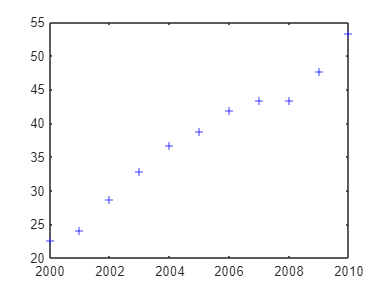

close all
% Vi börjar med att skapa två vektorer med mätdata
year      = [2000, 2001, 2002, 2003, 2004, 2005, 2006, 2007, 2008, 2009, 2010]; % År
sea_level = [22.6, 24.1, 28.7, 32.9, 36.7, 38.8, 41.9, 43.3, 43.3, 47.6, 53.3]; % Global vattennivåhöjning sedan 1993 [mm]

% Vi vill plotta "year" på x-axeln och "sea_level" på y-axeln
plot(year, sea_level, "Marker", "+", "Color", "blue", "LineStyle", "none")

% "Marker"    - hur våra datapunkter ska se ut (t.ex. "+", "o", "x", ">", "*" o.s.v)
% "Color"     - vilken färg våra datapunkter ska ha
% "LineStyle" - hur linjen mellan punkterna ska se ut (t.ex. "none", "-", "--" o.s.v)

Det saknas etiketter på x- och y-axel. Dessa läggs till med xlabel() och ylabel() funktionerna.

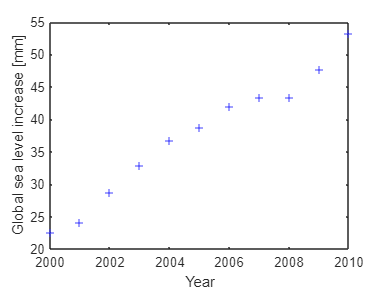

xlabel("Year")
ylabel("Global sea level increase [mm]")

Vi vill lägga till en linjär anpassning till vårt data set på formen $y = kx + m$

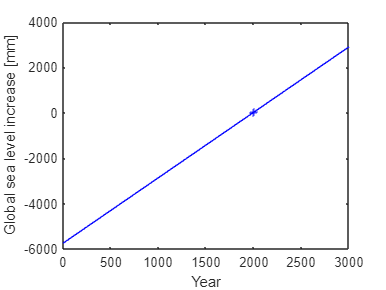

x_modell = linspace(0, 3000); % Definierar x-axeln (linspace ger 100 punkter mellan 0 och 3000 i detta fall)

k = 2.8845; % Lutning
m = -5746;  % Skärningspunkt
y_modell = k .* x_modell + m; % Beräknar y(x) för vår linjära modell

hold on % Detta låter oss plotta i samma fönster som senast definierats
plot(x_modell, y_modell, "LineStyle", "-", "Color", "blue")
hold off

Vår x-axel går nu från år 0 till år 3000 (man ser knappt datapunkterna längre), detta är knappast en rimlig *range*. Ändra till en rimlig *range* med xlim() funktionen

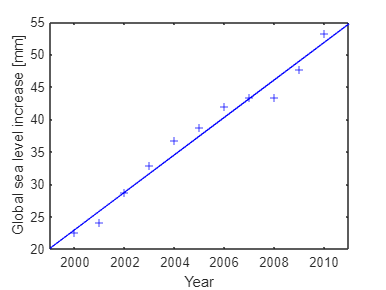

start_year = 1999;
end_year = 2011;
xlim([start_year, end_year])

Slutligen vill vi lägga till en *legend* som beskriver vad som är vad i figuren.

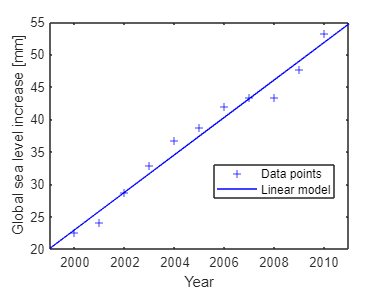

text_1 = "Data points";
text_2 = "Linear model";
legend(text_1, text_2, "Location", "best") % "Location", "best" innebär att Matlab placerar textlådan där den tror det är rimligt

### Vi har nu skapat en värdig figur!

Du kan nu gå vidare till Föreläsning 2 - Mätvärdesbehandling i Studium.